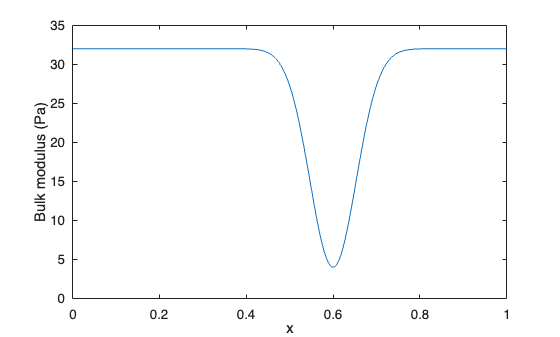

% Demo: multipole sources in the staggered 1D acoustic solver
clear
close all
clc

% Grid
pressureGrid = GridSpace1D(Grid1DUnifPrimal([0,1],401));
velocityGrid = GridSpace1D(Grid1DUnifDual(pressureGrid.x));
outputGrid = GridSpace1D(Grid1DUnifPrimal([0,1],201));

% Medium
medium = AcousticMedium1D.gaussianDip( ...
    BetaRange=[0.25,0.5], ...
    KappaRange=[4,32], ...
    Center=0.6, ...
    Width=0.075);
[kappa,beta,wspeed,cMax] = sampleMedium1D(pressureGrid,medium);

kappa.plot;

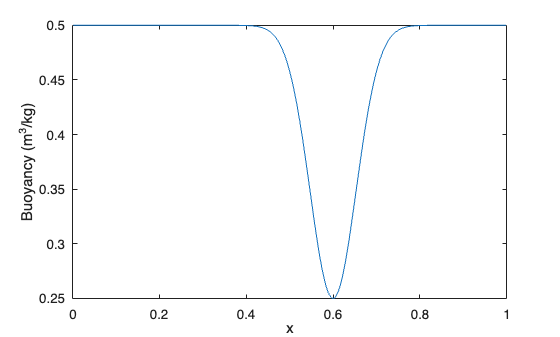

beta.plot;

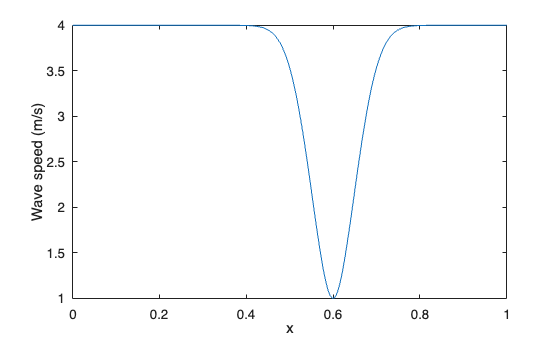

wspeed.plot;


% Time grid
dt = 0.8*(6/7)*pressureGrid.h/cMax;
times = 0:dt:0.8;
outputTimes = linspace(0,times(end),81);

% Define two multipole terms
% An order-zero pressure monopole at x=0.35.
monopole = MultipoleTerm1D( ...
    0.33,0,@(t) exp(-((t-0.10)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

% A first derivative of delta at x=0.65. This produces a dipole-like
% signed spatial source. Its time pulse is delayed relative to the first.
dipole = MultipoleTerm1D( ...
    0.8,1,@(t) exp(-((t-0.18)/0.035).^2), ...
    Amplitude=0.04,TargetField="pressure");

% Construct and discretize the multipole source
mps = MultipoleSource1D( ...
    [monopole,dipole],ApproximationOrder=4);
source = mps.discretize(pressureGrid,velocityGrid);
% Initializing PML
pml = PML1D( ...
    WidthLeft=0.2, ...
    WidthRight=0.2, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Initialize solver
solver = AcousticSolver1D_PML( ...
    pressureGrid,times, ...
    outputGrid,outputTimes, ...
    medium, pml, ...
    SpatialOrder=4);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));


% Run solver
[P,V] = solver.solve(p0,v0,Source=source);

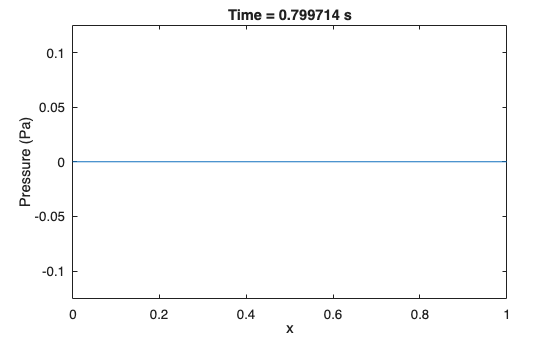

P.animate(FramePause=0.03);

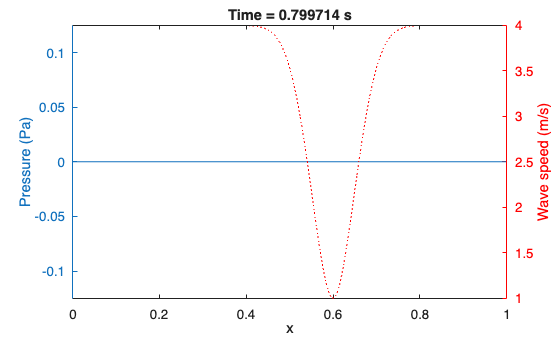

P.animateMedBack(medium);